clear
a=linspace(-5,5,75);
b=a;
% b=-20:0.2:20;
[p,q]=meshgrid(a,b);
alpha=p+1i*q;
alpha=reshape(alpha,[length(p)*length(q),1])

alpha =   -5.0000 - 5.0000i
  -5.0000 - 4.8649i
  -5.0000 - 4.7297i
  -5.0000 - 4.5946i
  -5.0000 - 4.4595i
  -5.0000 - 4.3243i
  -5.0000 - 4.1892i
  -5.0000 - 4.0541i
  -5.0000 - 3.9189i
  -5.0000 - 3.7838i


alpha_mod=sqrt(p.^2+q.^2);
theta=atan2(p,q);
Kb=1.38e-23;
T=.1;
h=6.626e-34;
nu_oscillator=5e9;
beta=h*nu_oscillator/Kb/T;
beta_temp=beta;
average_occupation=1/(exp(beta)-1)

average_occupation = 0.0997

thermal_husimi=1/2/pi*(1-exp(-beta)).*exp(-(1-exp(-beta))/2.*(q.^2+p.^2));
thermal_husimi_column=reshape(thermal_husimi,[length(p)*length(q),1]);

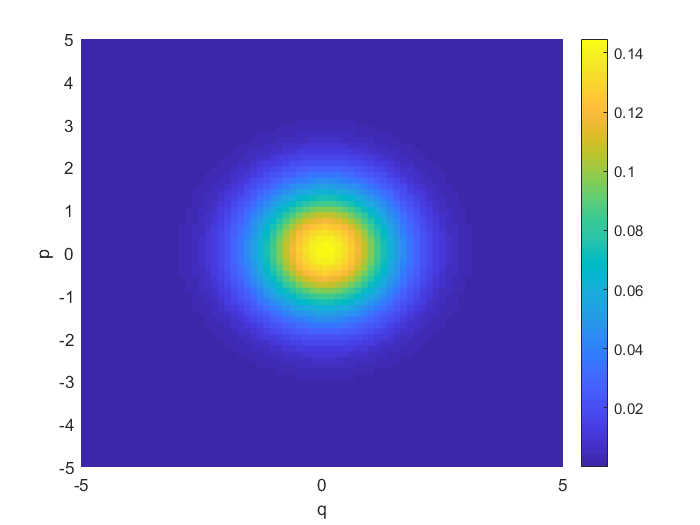

figure
s=surf(q,p,thermal_husimi);
xlabel('q');
ylabel('p');
zlabel('Q(q,p)');
set(s,'LineStyle','none'); 
view(0,90)
colorbar

fock_space_size=30;
initial_density_matrix=diag(1/fock_space_size.*ones(fock_space_size,1));

fock_vector=0:1:fock_space_size-1;
theory_density_matrix=exp(-beta_temp.*(fock_vector+1/2)).*(1-exp(-beta_temp));
theory_density_matrix=diag(theory_density_matrix);
% fock_basis_a=zeros(length(alpha),length(alpha),fock_space_size,fock_space_size);
% fock_basis_b=fock_basis_a;
% alpha_vector_a=fock_basis_a;
% alpha_vector_b=fock_basis_b;

fock_basis_a_temp=repmat(fock_vector,[fock_space_size,1]);
fock_basis_a=repmat(fock_basis_a_temp,[1,1,length(alpha)]);
fock_basis_b=fock_basis_a;
fock_basis_b=permute(fock_basis_b,[2,1,3]);
alpha_vector_temp=repmat(alpha,[1,fock_space_size]);
alpha_vector_a=repmat(alpha_vector_temp,[1,1,fock_space_size]);
alpha_vector_a=permute(alpha_vector_a,[3,2,1]);
% 1/pi*exp(-abs(squeeze(alpha_vector_a(:,:,3)).^2)).*((squeeze(alpha_vector_a(:,:,3))).^squeeze(fock_basis_a(:,:,3))).*conj(squeeze(...
%     alpha_vector_a(:,:,3)).^squeeze(fock_basis_b(:,:,3)))./sqrt(factorial(squeeze(fock_basis_a(:,:,3))).*factorial(squeeze(fock_basis_b(:,:,3))))

pi_a=1/pi*exp(-abs(alpha_vector_a).^2).*((alpha_vector_a).^fock_basis_a).*(conj(alpha_vector_a).^fock_basis_b)./sqrt(factorial(...
    fock_basis_a).*factorial(fock_basis_b));
G=sum(pi_a,3);
G_inv=inv(G);
G*G_inv

ans =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i
  -0.0000 - 0.0000i   1.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.

current_density_matrix=initial_density_matrix

current_density_matrix =     0.0333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.0333         0         0         0  

number_iterations=35;
density_matrix_iteration=zeros(fock_space_size,fock_space_size,number_iterations);
r_iteration=zeros(fock_space_size,fock_space_size,number_iterations);
log_likelihood_iteration=zeros(number_iterations,1);
i=0;
for i=1:number_iterations
     old_density_matrix=current_density_matrix;
     pi_temp=permute(pi_a,[1 3 2]);
     pi_temp=reshape(pi_temp,[fock_space_size*length(alpha),fock_space_size]);
     pi_rho_temp=pi_temp*old_density_matrix;
     pi_rho=reshape(pi_rho_temp',size(pi_a));
     pi_rho=permute(pi_rho,[2,1,3]); 
     pi_rho_diag=eye(fock_space_size,fock_space_size).*pi_rho;
     pi_rho_trace=squeeze(sum(sum(pi_rho_diag,2),1));
     r_coeff=thermal_husimi_column./pi_rho_trace;
     likelihood_temp=thermal_husimi_column.*log(pi_rho_trace);
     likelihood=sum(likelihood_temp);
     log_likelihood_iteration(i,1)=likelihood;
     r_coeff_temp=repmat(r_coeff,[1,fock_space_size]);
     r_coeff_temp=repmat(r_coeff_temp,[1,1,fock_space_size]);
     r_coeff_temp=permute(r_coeff_temp,[2,3,1]);
     r=r_coeff_temp.*pi_a;
     r=sum(r,3);
%      r_test=r;
%      r_test(abs(imag(r))>eps(max(max(imag(r)))))=0
     r_iteration(:,:,i)=r;
     current_density_matrix=G_inv*r*old_density_matrix*r*G_inv;
     
     current_density_matrix=current_density_matrix/trace(current_density_matrix);
     density_matrix_iteration(:,:,i)=current_density_matrix;
     trace_iteration(i,1)=trace(current_density_matrix);
%      error=mean(mean(abs(current_density_matrix-old_density_matrix)))
     error(i,1)=norm(current_density_matrix-old_density_matrix,Inf)/norm(old_density_matrix,Inf);
end
current_density_matrix

current_density_matrix =    0.4547 + 0.0000i  -0.0003 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i
   0.0003 + 0.0000i   0.2479 + 0.0000i  -0.0002 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.

trace(current_density_matrix)

ans = 1.0000 - 0.0000i

trace(theory_density_matrix)

ans = 0.3011

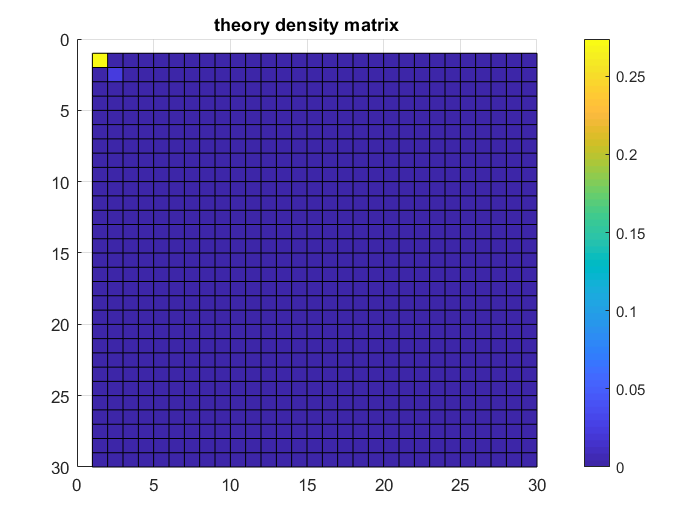

figure
surf(abs(theory_density_matrix))
title('theory density matrix')
colorbar
view(0,270)

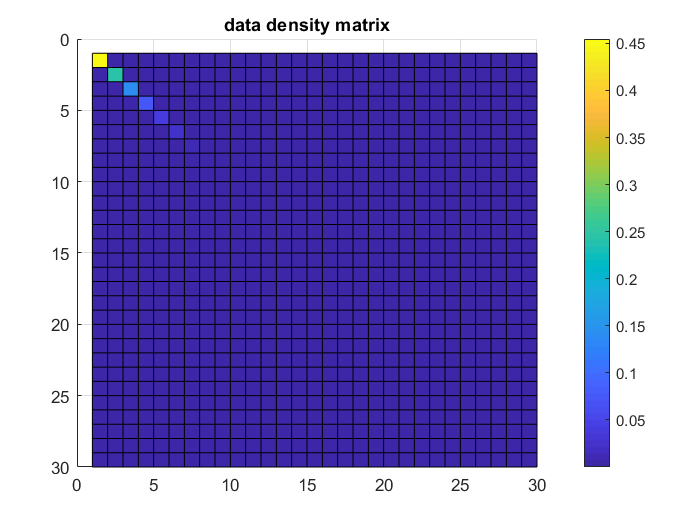

figure
surf(abs(current_density_matrix))
title('data density matrix')
colorbar
view(0,270)

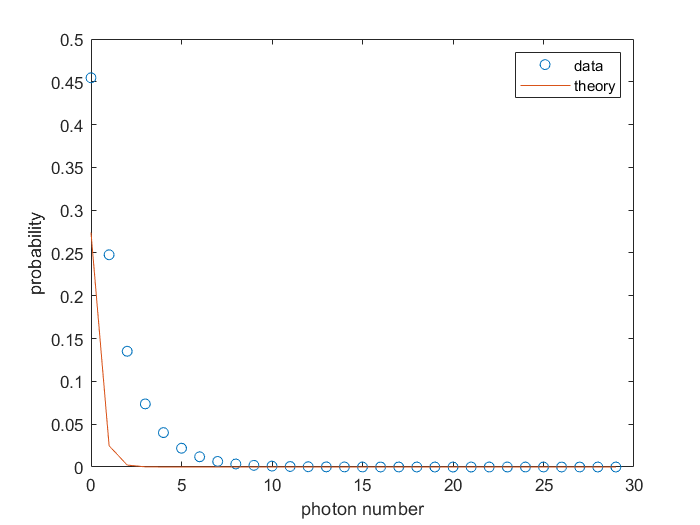

figure
plot(fock_vector,diag(abs(current_density_matrix)),'o')
hold on
plot(fock_vector,diag(abs(theory_density_matrix)))
legend('data','theory')
xlabel('photon number')
ylabel('probability')

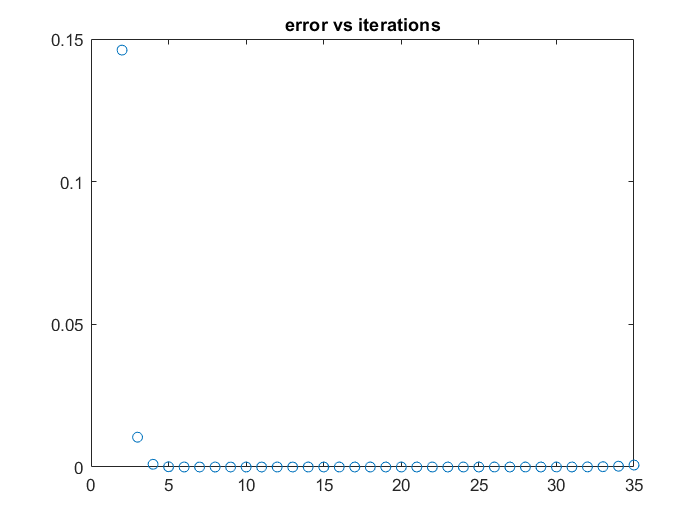

figure
error_plot=error(2:end,1);
test=2:1:number_iterations;
plot(test,error_plot,'o')
title('error vs iterations')

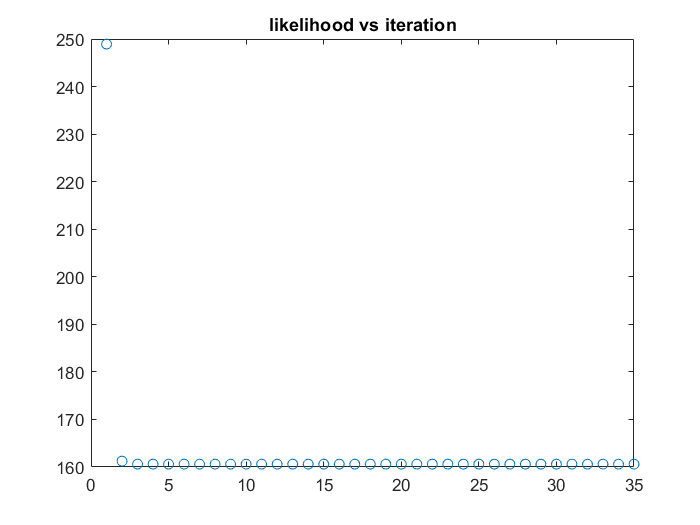

figure
plot(abs(log_likelihood_iteration),'o')
title('likelihood vs iteration')

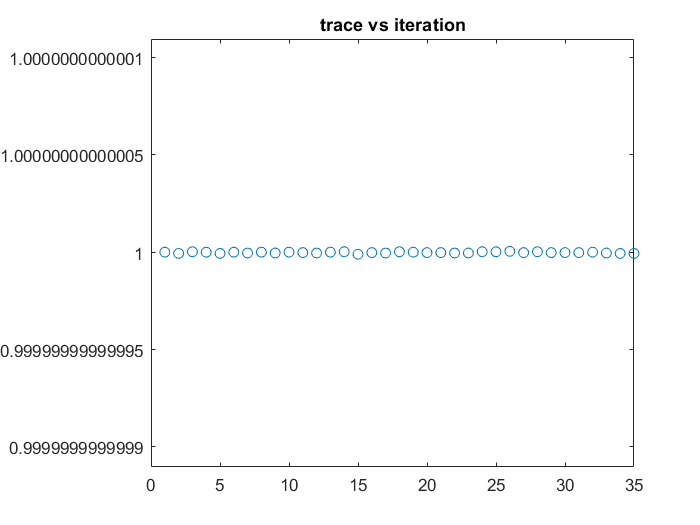

figure
plot(abs(trace_iteration),'o')
title('trace vs iteration')

% for i=1:number_iterations
%     density_matrix_iteration_temp=squeeze(density_matrix_iteration(:,:,i));
%     density_matrix_diag_iteration(:,i)=diag(density_matrix_iteration_temp);
%     real_test(i,1)=isreal(density_matrix_diag_iteration(:,i));
% end
% figure
% plot(real_test,'o')

n=43;
r_iteration(:,:,n)

Index in position 3 exceeds array bounds (must not exceed 35).

density_matrix_iteration(:,:,n)
trace_iteration(n)
r_iteration(:,:,n+1)
density_matrix_iteration(:,:,n+1)
trace_iteration(n+1)
r_iteration(:,:,n+2)
density_matrix_iteration(:,:,n+2)
trace_iteration(n+2)
d

% n=7;
% density_matrix_iteration(:,:,end-n);
% density_matrix_iteration(:,:,end-n-1);
% figure
% surf(abs(density_matrix_iteration(:,:,end-n)))
% title(['density matrix iteration number ' num2str(number_iterations-n)])
% view(0,270)
% figure
% surf(abs(density_matrix_iteration(:,:,end-n-1)))
% title(['density matrix iteration number ' num2str(number_iterations-n-1)])
% view(0,270)
% trace_iteration

% tol=1e-3;
% for j=1:number_iterations
%     r_temp=r_iteration(:,:,j)./max(max(abs(r_iteration(:,:,j))));
%     r_temp=squeeze(r_temp)-eye(fock_space_size);
%     r_logic(abs(r_temp)<tol)=0;
%     r_logic(abs(r_temp)>tol)=1;
%     r_matrix=diag(r_logic);
%     figure
%     surf(r_matrix)
%     colorbar
%     view(0,270)
%     title(num2str(j))  
%     figure
%     surf(abs(r_iteration(:,:,j)))
%     colorbar
%     title(num2str(j))
%     view(0,270)
% end




























% gamma_coeff_vectorized=zeros(length(p)*length(q),length(p)*length(q),fock_space_size,fock_space_size);
% kappa_coeff_vectorized=zeros(length(p)*length(q),fock_space_size,fock_space_size);
% coeff_vectorized=zeros(length(p)*length(q),length(p)*length(q),fock_space_size,fock_space_size);
% fock_space_vector=0:1:fock_space_size-1;
% for aa=1:size(gamma_coeff_vectorized,1)
%     kappa_coeff_temp=conj(alpha(aa)).^fock_space_vector'*alpha(aa).^fock_space_vector./sqrt(factorial(fock_space_vector)'*factorial(fock_space_vector));
%     kappa_coeff_vectorized(aa,:,:)=kappa_coeff_temp;
%     for bb=1:size(gamma_coeff_vectorized,2)
%         gamma_coeff_temp=conj(alpha(aa)).^fock_space_vector'*alpha(bb).^fock_space_vector./sqrt(factorial(fock_space_vector)'*factorial(fock_space_vector));
%         gamma_coeff_vectorized(aa,bb,:,:)=gamma_coeff_temp;
%         coeff_temp=thermal_husimi_column(aa)*thermal_husimi_column(bb)*(alpha(aa).^fock_space_vector)'*conj(alpha(bb)).^fock_space_vector./...
%             sqrt(factorial(fock_space_vector)'*factorial(fock_space_vector));
%         coeff_vectorized(aa,bb,:,:)=coeff_temp;
%     end
% end

% 
% % while error>1e-3
% %     i=i+1
% for i=1:number_iterations
%     old_density_matrix=current_density_matrix;
%     kappa=zeros(length(p)*length(q),fock_space_size,fock_space_size);
%     kappa_temp=zeros(fock_space_size,fock_space_size);
%     gamma=zeros(length(p)*length(q),length(p)*length(q),fock_space_size,fock_space_size);
%     gamma_temp=zeros(fock_space_size,fock_space_size);
%     for aa=1:size(kappa,1)
%         kappa_temp(:)=kappa_coeff_vectorized(aa,:,:);
%         kappa(aa,:,:)=kappa_temp.*old_density_matrix';
%         for bb=1:size(gamma,2)
%             gamma_temp(:)=gamma_coeff_vectorized(aa,bb,:,:);
%             gamma(aa,bb,:,:)=gamma_temp.*old_density_matrix;
%         end
%     end
%     kappa=sum(sum(kappa,3),2);
%     gamma=sum(sum(gamma,4),3);
%     kappa_inverse=1./kappa;
%     kappa_inverse_product=kappa_inverse'*kappa_inverse;
%     for aa=1:fock_space_size
%         for bb=1:fock_space_size
%             coeff_element=coeff_vectorized(:,:,aa,bb);
%             current_density_matrix_temp=kappa_inverse_product.*gamma.*coeff_element;
%             current_density_matrix_element=sum(sum(current_density_matrix));
%             current_density_matrix(aa,bb)=current_density_matrix_element;
%         end
%     end
%     current_density_matrix=current_density_matrix/trace(current_density_matrix)
%     error=mean(mean(abs(current_density_matrix-old_density_matrix)))
% end
% current_density_matrix

% % gamma=zeros(length(p)*length(q),length(p)*length(q),fock_space_size,fock_space_size);
% % gamma_vectorized=gamma;
% % kappa_coeff=zeros(length(p)*length(q),fock_space_size,fock_space_size);
% % kappa_coeff_vectorized=kappa_coeff;
% % fock_space_vector=0:1:fock_space_size-1;
% % psi=zeros(length(p)*length(q),length(p)*length(q),fock_space_size,fock_space_size);
% % % fock_vector=0:1:fock_space_size;
% % for aa=1:size(gamma,1)   %alpha
% %     for bb=1:size(gamma,2)   %beta
% %         gamma_temp=conj(alpha(aa)).^fock_space_vector'*(alpha(bb).^fock_space_vector)./sqrt(factorial(fock_space_vector)'*factorial(fock_space_vector));
% %         size(gamma_temp)
% %         gamma_vectorized(aa,bb,:,:)=gamma_temp;
% %         kappa_coeff_temp=conj(alpha(aa)).^fock_space_vector'*(alpha(aa).^fock_space_vector)./sqrt(factorial(fock_space_vector)'*factorial(fock_space_vector));
% %         kappa_coeff_vectorized(aa,:,:)=kappa_coeff_temp;
% %         for cc=1:size(gamma,3)    %m
% %             for dd=1:size(gamma,4)    %n
% %                 gamma(aa,bb,cc,dd)=conj(alpha(aa))^(cc-1)*alpha(bb)^(dd-1)/sqrt(factorial(cc-1)*factorial(dd-1));
% %                 kappa_coeff(aa,cc,dd)=alpha(aa)^(cc-1)*conj(alpha(aa))^(dd-1)/sqrt(factorial(cc-1)*factorial(dd-1));
% %             end
% %         end
% %     end
% % end
% % gamma_vectorized=sum(sum(gamma_vectorized,4),3);
% % gamma=sum(sum(gamma,4),3);
% % gamma-gamma_vectorized
% % for aa=1:size(psi,1)   % alpha
% %     for bb=1:size(psi,2)    % beta
% %         for cc=1:size(psi,3)  %m
% %             for dd=1:size(psi,4)   %n
% %                 psi(aa,bb,cc,dd)=thermal_husimi_column(aa)*thermal_husimi_column(bb)*gamma(aa,bb)*alpha(aa)^(cc-1)*conj(alpha(bb))^(dd-1)...
% %                     /sqrt(factorial(cc-1)*factorial(dd-1));
% %             end 
% %         end
% %     end
% % end

% % temp_disp=zeros(fock_space_size,fock_space_size);
% % temp_disp(:)=kappa_coeff(64,:,:)
% % alpha
% % % size(temp_disp)
% % gamma
% % % psi

% % current_density_matrix=initial_density_matrix;
% % current_density_matrix_vectorized=current_density_matrix;
% % temp_coeff=zeros(fock_space_size,fock_space_size,length(p)*length(q),length(p)*length(q));
% % temp_coeff_vectorized=temp_coeff;
% % number_iterations=21;
% % error=1;
% % i=0;
% % % while error>1e-3
% % %     i=i+1;
% % for i=1:number_iterations
% %     i;
% %     old_density_matrix=current_density_matrix_vectorized;
% %     kappa=zeros(length(p)*length(q),fock_space_size,fock_space_size);
% %     kappa_temp=zeros(fock_space_size,fock_space_size);
% %     for aa=1:size(kappa,1)   %alpha
% % %         for bb=1:size(kappa,2)    %m
% % %             for cc=1:size(kappa,3)   %n
% %                 kappa_temp(:)=kappa_coeff(aa,:,:);
% %                 kappa(aa,:,:)=kappa_temp.*old_density_matrix;
% % %                 kappa(aa,bb,cc)=kappa_coeff(aa,bb,cc)*old_density_matrix(cc,bb);
% % %             end
% % %         end
% %     end
% %     kappa=sum(sum(kappa,3),2);
% %     kappa_inverse=1./kappa;
% %     psi_temp=zeros(length(p)*length(q),length(p)*length(q));
% %     for aa=1:size(temp_coeff_vectorized,1)   % m
% %         for bb=1:size(temp_coeff_vectorized,2)    % n
% %             psi_temp(:)=psi(:,:,aa,bb);
% %             temp_coeff_vectorized(aa,bb,:,:)=psi_temp.*(kappa_inverse*kappa_inverse');
% %             temp_density_matrix_vectorized=sum(sum(temp_coeff_vectorized,4),3);
% %             current_density_matrix_vectorized(aa,bb)=temp_density_matrix_vectorized(aa,bb);
% %         end
% %     end
% % %     for aa=1:size(temp_coeff,1)    % m
% % %         for bb=1:size(temp_coeff,2)    %n
% % %             for cc=1:size(temp_coeff,3)     %alpha
% % %                 for dd=1:size(temp_coeff,4)    %beta
% % %                       temp_coeff(aa,bb,cc,dd)=psi(cc,dd,aa,bb)/kappa(cc)/kappa(dd);
% % %                 end
% % %             end
% % %             temp_density_matrix=sum(sum(temp_coeff,4),3);
% % %             current_density_matrix(aa,bb)=temp_density_matrix(aa,bb);
% % %         end
% % %     end
% %     current_density_matrix_vectorized=current_density_matrix_vectorized/trace(current_density_matrix_vectorized);
% % %     current_density_matrix=current_density_matrix/trace(current_density_matrix);
% %     error=mean(mean(abs(current_density_matrix_vectorized-old_density_matrix)))
% % end
% % % current_density_matrix
% % current_density_matrix_vectorized